# Ejercicio N°8

## Respuesta al impulso

syms C1 C2 C3 C4 C5 C6 s R1 R2 E1 v1 v2 v3 v4;

La matriz de admitancias

Y=[1/R1+s*C1+s*C5 -s*C5 -s*C1 0; -s*C5 s*C5+s*C2+1/R2 0 -s*C2;-s*C1 0 s*C1+s*C3+s*C6 -s*C6;0 -s*C2 -s*C6 s*C6+s*C4+s*C2]

$$Y = \left(\begin{array}{cccc} C_{1}\,s+C_{5}\,s+\frac{1}{R_{1}} & -C_{5}\,s & -C_{1}\,s & 0\\ -C_{5}\,s & C_{2}\,s+C_{5}\,s+\frac{1}{R_{2}} & 0 & -C_{2}\,s\\ -C_{1}\,s & 0 & C_{1}\,s+C_{3}\,s+C_{6}\,s & -C_{6}\,s\\ 0 & -C_{2}\,s & -C_{6}\,s & C_{2}\,s+C_{4}\,s+C_{6}\,s \end{array}\right)$$

Is=[E1/R1;0;0;0]

$$Is = \left(\begin{array}{c} \frac{E_{1}}{R_{1}}\\ 0\\ 0\\ 0 \end{array}\right)$$

x=[v1;v2;v3;v4];
Y\(Is)==x;
eqs=Y*x==Is;
solu=solve(eqs);

Reemplazando los valores del circuito

C1=1;C2=2;C3=3;C4=4;C5=5;C6=6;R1=1;R2=1;E1=1;

La función de transferencia $ H(s)=V2(s)/E(s)$

v2s=subs(solu.v2)

$$v2s = \frac{432\,s}{988\,s^{2}+1040\,s+84}$$

La respuesta al impulso es

vpa(rewrite(ilaplace(v2s),'exp'),4)

$$ans = 0.4372\,{\mathrm{e}}^{-0.5263\,t}\,\left(1.101\,{\mathrm{e}}^{-0.4382\,t}-0.1006\,{\mathrm{e}}^{0.4382\,t}\right)$$


$$v2(t)=0.4813 e^{-0.9645t}-0.04398e^{-0.0881t}$$


## Solución con Backward-Euler

clear all;
% Valores de los componentes
R1=1;R2=1;C1=1;C2=2;C3=3;C4=4;C5=5;C6=6;
% Matrices forma general
M=[C1*R1 0 C5*R1 0;-R2*C2 0 (C5*R2+R2*C2) -R2*C2; C1 -C3 0 -C6;C2 -C4 -C2 C6+C4+C2];
N=[1 1 0 0;-1 -1 1 0;0 0 0 0;0 0 0 0];
% Matriz forma normal
A=-1.*(M\N);
% Condiciones iniciales
v01=0;v02=0;v03=0;v04=0;v05=0;v06=0;
Xant=[v01;v03;v05;v06];

clear  t
solu=[];
ti=0;
tf=10;
h=0.1;
for t=ti:h:tf
    if t<=5
    E=(sin(0.2*pi*t))^2;
    else
     E=0;
    end
    u=[E;0;0;0];
     X=((((1/h).*M)+N)\u) + ((((1/h).*M)+N)\((1/h).*M)*Xant);
    solu=[solu X];
    Xant=X;
end
t=ti:h:tf;

vr2=solu(1,:)+solu(2,:)-solu(3,:);
plot(t,vr2)
hold on;

## Solución convolución numérica

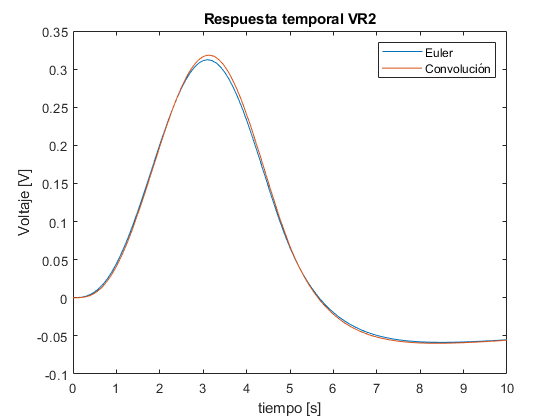

clear all;
syms t tau  
E= sin(pi/5*tau)^2*(heaviside(tau)-heaviside(tau-5));
imp=0.4813*exp(-0.9645*(t-tau))-0.0440*exp(-0.0882*(t-tau));
v2int=int(imp*E,tau,0,t);
fplot(v2int,[0,10])
hold off;

legend({'Euler','Convolución'})
title('Respuesta temporal VR2')
xlabel('tiempo [s]')
ylabel('Voltaje [V]')